# Dimensionering af en varmepumpe til kraftvarmeværk

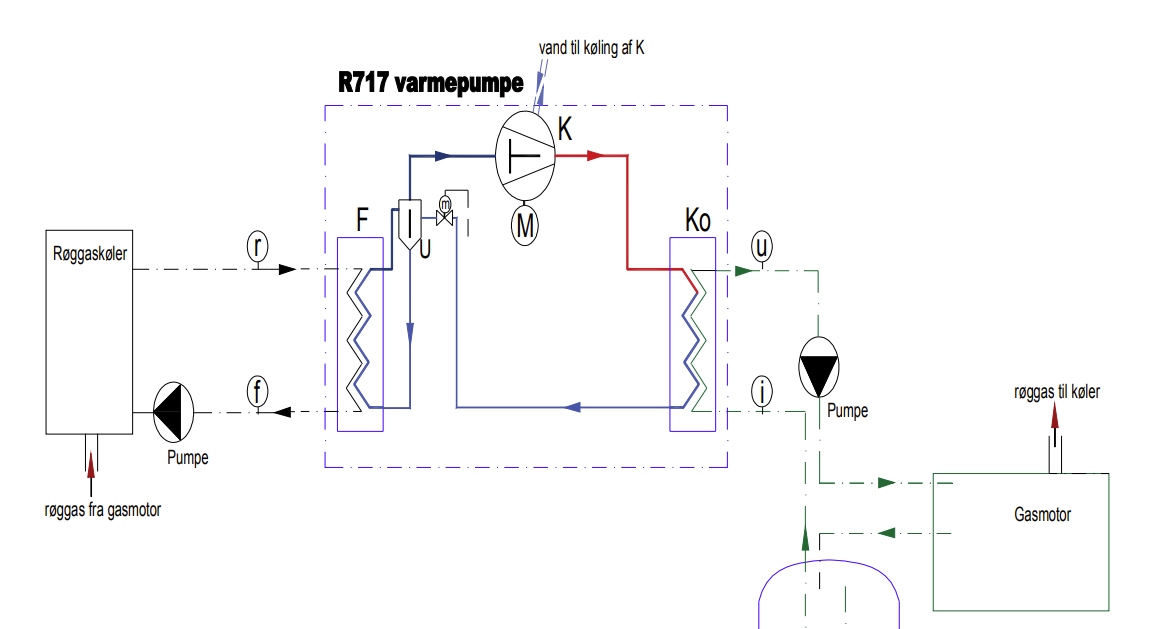

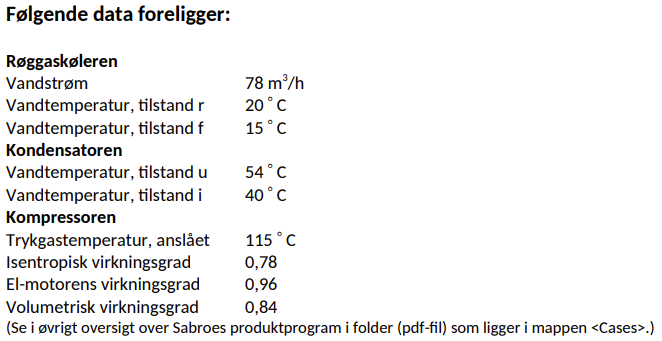

clc; clear all;
u = symunit;


%----------------------------------------------%
%--------------- Røggaskøleren ----------------%
%----------------------------------------------%
q_V = 78 * u.m^3/u.h;
rho_V = 999.1 * u.kg/u.m^3;
cp_V = 4182 * u.J/(u.kg*u.K);

t_r = 20*u.K;
t_f = 15*u.K;


phi_RK = q_V*rho_V*cp_V*(t_r - t_f);
phi_RK = vpa(unitConvert(phi_RK, u.kW), 3)

$$phi\_RK = 453.0\,\mathrm{kW}$$


% Temperatur fra gassiden af fordamperen

t_gas_anataget = 60*u.K;



%----------------------------------------------%
%--------------- Kondensatoren ----------------%
%----------------------------------------------%


% NH3
t_nh3_ind = 115*u.K;
t_nh3_ud = 60*u.K; % ANTAGET VÆRDI

cp_NH3 = 12.86 * u.kJ/(u.kg*u.K);
rho_NH3 = 85.05 * u.kg/u.m^3;

eta_v = 0.84;
q_Vs_komp = 200 * u.m^3/u.h;

qV_NH3 = eta_v * q_Vs_komp;
qV_NH3 = vpa(unitConvert(qV_NH3, u.m^3/u.h), 3)

$$qV\_NH3 = 168.0\,\frac{m^{3}}{h}$$


phi_kond_NH3 = qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ind - t_nh3_ud);
phi_kond_NH3 = vpa(unitConvert(phi_kond_NH3, u.kW), 3)

$$phi\_kond\_NH3 = 2810.0\,\mathrm{kW}$$



% Vandstrømmen der køler

t_kond_vi = 40 * u.K;
t_kond_vu = 54 * u.K;

syms qV_vand_kond
phi_kond_vand = qV_vand_kond*rho_V*cp_V*(t_kond_vu - t_kond_vi);

eq = phi_kond_vand == phi_kond_NH3;

qV_vand_kond = solve(eq, qV_vand_kond);
qV_vand_kond = vpa(unitConvert(qV_vand_kond, u.m^3/u.h), 3)

$$qV\_vand\_kond = 173.0\,\frac{m^{3}}{h}$$



% Kondensatorens 3 ydelser

phi_kond_NH3 = qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ind - 105*u.K);
phi_kond_NH3 = vpa(unitConvert(phi_kond_NH3, u.kW), 3)

$$phi\_kond\_NH3 = 510.0\,\mathrm{kW}$$


phi_kond_NH3 = qV_NH3 * rho_NH3 * cp_NH3 * (105*u.K - t_nh3_ud);
phi_kond_NH3 = vpa(unitConvert(phi_kond_NH3, u.kW), 3)

$$phi\_kond\_NH3 = 2300.0\,\mathrm{kW}$$


phi_kond_NH3 = qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ud - 50*u.K);
phi_kond_NH3 = vpa(unitConvert(phi_kond_NH3, u.kW), 3)

$$phi\_kond\_NH3 = 510.0\,\mathrm{kW}$$

syms Phi_v qV_v rho_v cp_v t_vu t_fi

% Phi for vand ved kondensator
Phi_v = qV_v*rho_v*cp_v*(t_vu*t_fi)

$$Phi\_v = {\mathrm{cp}}_{v}\,{\mathrm{qV}}_{v}\,\rho_{v}\,t_{\mathrm{fi}}\,t_{\mathrm{vu}}$$



% Phi for NH3 ved kondensator
syms Phi_NH3 qV_NH3 rho_NH3 cp_NH3 t_NH3_vu t_NH3_fi
Phi_NH3 = qV_NH3*rho_NH3*cp_NH3*(t_NH3_vu*t_NH3_fi)

$$Phi\_NH3 = {\mathrm{cp}}_{\mathrm{NH3}}\,{\mathrm{qV}}_{\mathrm{NH3}}\,\rho_{\mathrm{NH3}}\,t_{\mathrm{NH3},\mathrm{fi}}\,t_{\mathrm{NH3},\mathrm{vu}}$$


% Hastighed fra kondensator ????
d_fordamp = 20*u.mm;

c_fordamp = 4*qV_NH3/(pi*d_fordamp^2);
c_fordamp = vpa(unitConvert(c_fordamp,"SI"), 3)

$$c\_fordamp = 3180.0\,{\mathrm{qV}}_{\mathrm{NH3}}\,\frac{1}{m^{2}}$$